clear all
sympref('AbbreviateOutput', false);
syms x x_dot y y_dot alpha alpha_dot beta beta_dot 
%s = [x y alpha beta]

%ds = [x_dot y_dot alpha_dot beta_dot]
syms m_b J_b J_p J_px J_py r_b g 
T_b = 1/2*(m_b + J_b/r_b^2)*(x_dot^2+y_dot^2);
T_p = 0.5*((J_px*alpha_dot^2+J_py*beta_dot^2)+J_b*(alpha_dot^2+beta_dot^2)+m_b*(x*alpha_dot+y*beta_dot)^2);
%T_p = 0.5*(J_b+J_p)*(alpha_dot^2+beta_dot^2)+0.5*m_b*(x*alpha_dot+y*beta_dot);
V = m_b*g*(x*sin(alpha) + y*sin(beta));
L = T_b + T_p - V;
syms tau_x tau_y
X = {x x_dot alpha alpha_dot y y_dot beta beta_dot};
par = {m_b,g,r_b,J_b,J_p};
Q_e = {0 tau_x 0 tau_y}; %l_x*cos(alpha) l_y*cos(beta)};
Q_i = {0 0 0 0};
ss8 = EulerLagrange(L,X,Q_i,Q_e,0,par)

X = cell2sym(X)

$$X = \left(\begin{array}{cccccccc} x & \dot{x} & \alpha & \dot{\alpha } & y & \dot{y} & \beta & \dot{\beta } \end{array}\right)$$

## Nonlinear Model:

ss4 = [ss8(1:2); ss8(5:6)]

$$ss4 = \left(\begin{array}{c} \dot{x}\\ \frac{{r_{b}}^{2}\,\left(m_{b}\,x\,{\dot{\alpha }}^{2}+\dot{\beta }\,m_{b}\,y\,\dot{\alpha }-g\,m_{b}\,\sin\left(\alpha \right)\right)}{m_{b}\,{r_{b}}^{2}+J_{b}}\\ \dot{y}\\ \frac{{r_{b}}^{2}\,\left(m_{b}\,y\,{\dot{\beta }}^{2}+\dot{\alpha }\,m_{b}\,x\,\dot{\beta }-g\,m_{b}\,\sin\left(\beta \right)\right)}{m_{b}\,{r_{b}}^{2}+J_{b}} \end{array}\right)$$

X4 = [X(1:2) X(5:6)]

$$X4 = \left(\begin{array}{cccc} x & \dot{x} & y & \dot{y} \end{array}\right)$$

As = jacobian(ss4,X4)

$$As = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 \end{array}\right)$$

us = [alpha beta]

$$us = \left(\begin{array}{cc} \alpha & \beta \end{array}\right)$$

Bs = subs(jacobian(ss4,us),us,[0 0])*0.1750

$$Bs = \left(\begin{array}{cc} 0 & 0\\ -\frac{7\,g\,m_{b}\,{r_{b}}^{2}}{40\,\left(m_{b}\,{r_{b}}^{2}+J_{b}\right)} & 0\\ 0 & 0\\ 0 & -\frac{7\,g\,m_{b}\,{r_{b}}^{2}}{40\,\left(m_{b}\,{r_{b}}^{2}+J_{b}\right)} \end{array}\right)$$

consts = [g m_b r_b J_b];
g = 9.81;
m_b = 45.93;
r_b = 0.0213;
J_b = 2/5*m_b*r_b^2;
const = [g m_b r_b J_b];

A = double(subs(subs(As,consts,const),[alpha_dot beta_dot], [0 0]))

A =      0     1     0     0
     0     0     0     0
     0     0     0     1
     0     0     0     0


B = double(subs(Bs,consts,const))

B =          0         0
   -1.2263         0
         0         0
         0   -1.2263


% A = [0 1 0 0 
%      0 0 0 0 
%      0 0 0 1 
%      0 0 0 0 ];
% B = [0 -7.0071 0  0
%      0  0      0 -7.0071]';
C = [1 0 0 0
     0 0 1 0];
D = zeros(2,2);

sys = ss(A,B,C,D);

load data.mat

opt = stepDataOptions("StepAmplitude", deg2rad(-10))

opt =   step with properties:

      InputOffset: 0
    StepAmplitude: -0.1745


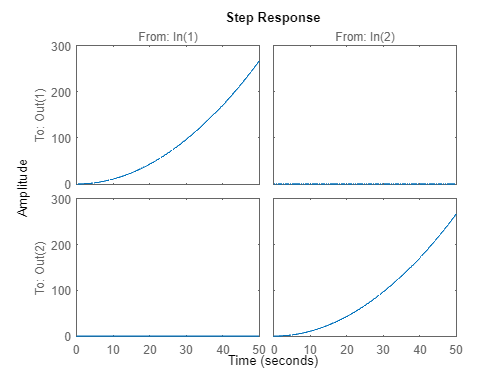

step(sys,opt)


cleanData;

'cleanData' is used in Use External Parameters in Parameterized Test.

t = 0:1/30:0.4;
u = ones(2,length(t))*deg2rad(30)
impulse(sys)


A = [ 0       1; 
      0       -2.2];
B = [0; -7];
C = eye(2);
D = zeros(2,1);
css = ss8(A,B,C,D);
dss = c2d(css, 1/30)
xData = BoPdataX(:,:,1,:);
compare(xData, css)
data = xData(:,1,1,1).OutputData

BoPdataX